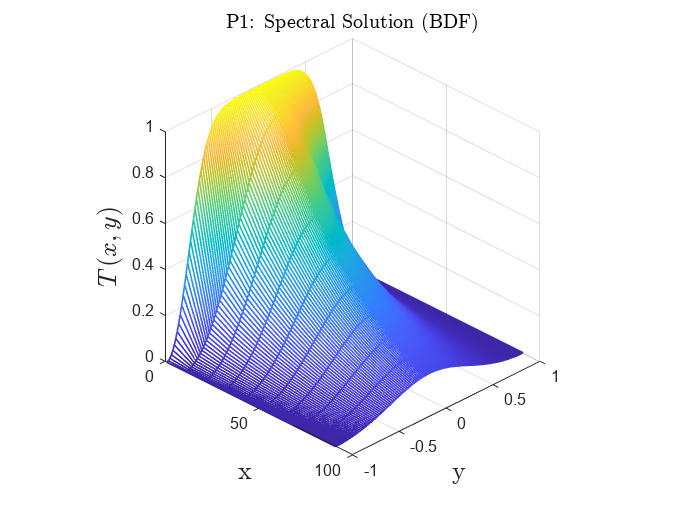

clear all
k = 2;                                                  % stencil size
nt = 100; tarr = linspace(0, 100, nt+1);                 % time array
dt = 100/nt;
ny = 128; yarr = linspace(-1, 1, ny);                    % space discretization
[X,Y] = meshgrid(tarr(2:end),yarr);

alpha = 0.01;                                            % conductivity
bk = [1.5 -2 0.5];
ak = 0 .* [2 -1];

u0 = ones(ny,1); u0(1)=0; u0(ny)=0;           % initial condition
u_arr = zeros(ny,nt+2);
u_arr(:,1) = u0;
u_arr(:,2) = u0;
[Ah,Bh,Ch,Dh,z,w] = semhat(ny-1);
R=eye(ny); R=R(2:end-1,:);
Ih = eye(ny);

A = alpha .* (R*Ah*R'); I = R*Ih*R';
y2 = 1 - yarr'.*yarr';
C = R*Ch*R'; B = R*(diag(y2) * Bh)*R'; Bt = R * Bh * R';
N = inv(B)*C; L = inv(B) * A;
[S,Lam]=gen_eig_decomp(A,B);
[S1,Lam1]=gen_eig_decomp(A,Bt);

for i=3:(nt+2)
    lhs = (bk(1) * I + dt .*L);
    rhs = - bk(2) .* (R * ( u_arr(:,i-1))) - bk(3) .* (R * ( u_arr(:,i-2))) + ak(1) .* (L * R *(u_arr(:,i-1))) + ak(2) .* (L * R *(u_arr(:,i-2)));
    u_arr(:,i) = R'*(inv(lhs) * (rhs));

    %hl = ( I + 0.5 .* dt .* alpha .*L);
    %hr = ( I - 0.5 .* dt .* alpha .*L);
    %u_arr(:,i) = R'*(inv(hl) * (hr) * (R * u_arr(:,i-1)));
end

sp = nt/10;
Xs = X(:,1:sp:end);
Ys = Y(:,1:(sp):end);
Us = u_arr(:,3:sp:end);

figure(1);
mesh(Xs,Ys,Us,EdgeColor="interp",LineWidth=1); axis square;
title('P1: Spectral Solution (BDF)','fontsize',12, Interpreter='latex')
xlabel('x','fontsize',16, Interpreter='latex'); ylabel('y','fontsize',16, Interpreter='latex');
zlabel('$T(x,y)$','fontsize',16, Interpreter='latex');
saveas(gcf,'Barchart.pdf')
view([45 30])

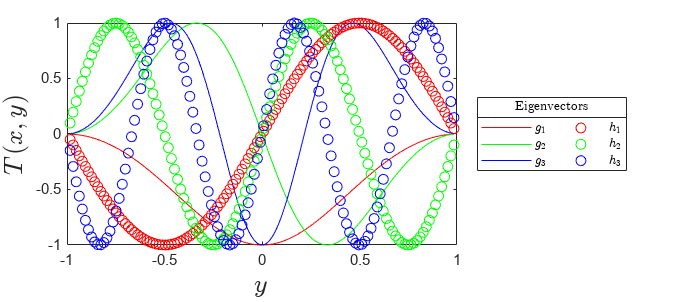

f = figure(2);
f.Position(3:4) = [900 400];
Ys = R*Y(:,1);
gcf;
%plot(Ys, S(:,1), 'r',Ys, S(:,2),'g', Ys, S(:,3),'b');
%hold on;
plot(Ys, S1(:,1), 'r', Ys, S1(:,2),'g', Ys, S1(:,3),'b');
hold on
plot(Ys, sin(pi.* Ys), 'ro', Ys, sin(2 .* pi .* Ys),'go', Ys, sin(3 .* pi .* Ys),'bo');

xlabel('$y$', FontSize=16, Interpreter='latex')
ylabel('$T(x,y)$', FontSize=16, Interpreter='latex')
lgd = legend(['$g_1$' "$g_2$" "$g_3$" '$h_1$' "$h_2$" "$h_3$"],FontSize=8, Interpreter="latex",Location="eastoutside");
lgd.NumColumns =2;
title(lgd,"Eigenvectors", Interpreter="latex")
hold off;

%pause(.3);

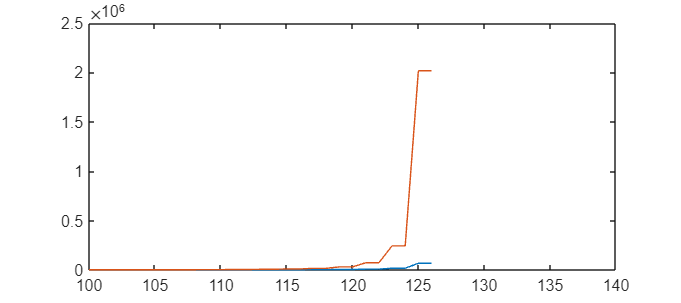

plot(diag(Lam1));
xlim([100 140])
hold on 
plot(diag(Lam));
hold off